# A AE 567 HW4 Problem1

% Housekeeping commands
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
outdir = pwd + "\output\hw4";
mdir = pwd + "\mfiles\hw4";

% Define expectations 
syms x v y g
y = x + v;
g = [1; y; y^2; y^3];
EX = @(A) int(1/4 * x.^A, 0, 4);
EV = @(A) int(1/2 * v.^A, -1, 1);
EY = @(A) 1/8 * int(int(y.^A, x, 0, 4), -1, 1);
EXY = @(A,B) 1/8 * int(int(x.^A * y.^B, x, 0, 4), -1, 1);

% P_Hx
Rfg = EXY(1, [0 1 2 3]);
A = [0:3; 1:4; 2:5; 3:6];
Rg = EY(A);
coef = Rfg * inv(Rg);
coef = eval(coef);
% Error d4
d4sq = EX(2) - Rfg*inv(Rg)*Rfg';
d4 = sqrt(d4sq);

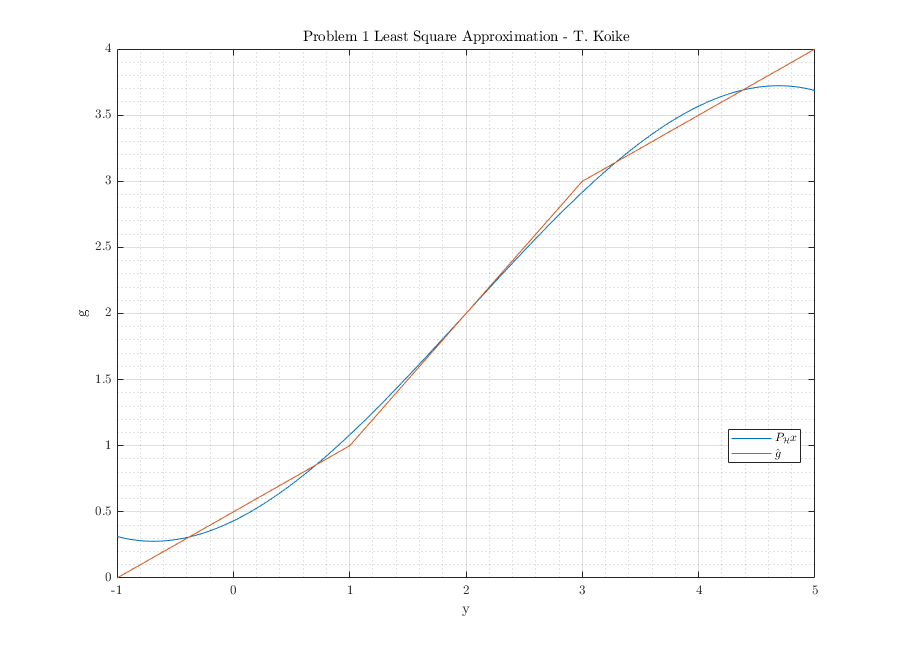

% Plotting
t = -1:0.01:5;
% ghat piecewise
t1 = t(-1 <= t & t < 1);
t2 = t(1 <= t & t < 3);
t3 = t(3 <= t & t <= 5);
ghat = [0.5*t1 + 0.5, t2, 0.5*t3 + 1.5];

Phx = coef(1) + coef(2)*t + coef(3)*t.^2 + coef(4)*t.^3;

fig = figure("Renderer","painters",'Position',[60 60 900 650]);
    plot(t, Phx)
    grid on; grid minor; box on; hold on;
    plot(t, ghat)
    hold off;
    title('Problem 1 Least Square Approximation - T. Koike')
    legend('$P_{\mathcal{H}}x$', '$\hat{g}$', "Location","best")
    xlabel('y')
    ylabel('g')
saveas(fig, fullfile(outdir, 'p1_lsqr_plot.png'));

% Save file as .m
matlab.internal.liveeditor.openAndConvert('hw4_p1.mlx', ...
    convertStringsToChars(fullfile(mdir, 'hw4_p1.m')));